clear all;
close all;

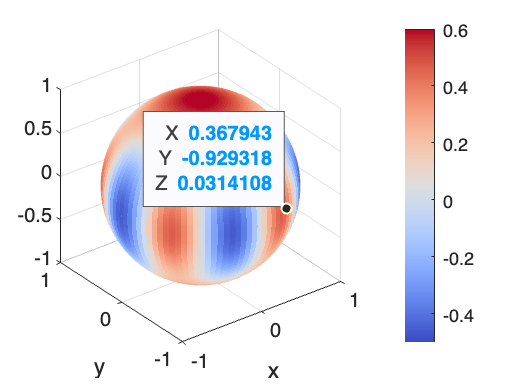

state=[1 0 0 0 0 1]'./sqrt(2);
rho_ideal=state*state';
wigner_plot(rho_ideal,100,100);

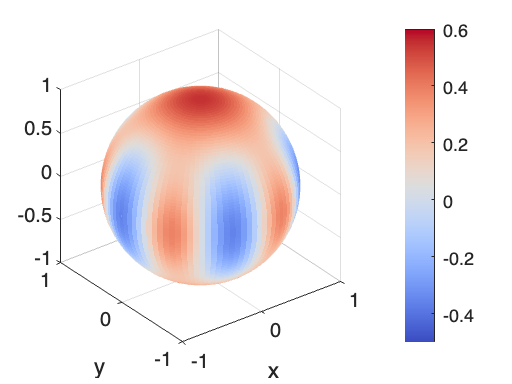

contrast=0.88375;
population_sum=0.9;
rho_expt=1/6*(1-population_sum)*eye(6);
rho_expt(1,1)=population_sum/2;
rho_expt(6,6)=population_sum/2;
rho_expt(1,6)=population_sum*contrast/2;
rho_expt(6,1)=population_sum*contrast/2;
wigner_plot(rho_expt,100,100);

state'*rho_expt*state

ans = 0.8477

function output=wigner_plot(rho,theta_num,phi_num)
    % OUTPUT=MATRIX RESULT(THETA,PHI)
    theta_list=[0:pi/theta_num:pi];
    phi_list=[0:2*pi/phi_num:2*pi];
    for i=1:length(theta_list)
        theta=theta_list(i);
        for j=1:length(phi_list)
            phi=phi_list(j);
            result(i,j)=trace(spin_wigner_operator(5/2,theta,phi)*rho);
        end
    end
    output=real(result);
    f1=figure;
    theta_list=pi/2-theta_list;
    [theta2,phi2]=meshgrid(theta_list,phi_list);
    [x,y,z]=sph2cart(phi2,theta2,1);
    surf=mesh(x,y,z,real(result'));
    xlim([-1 1]);
    zlim([-1 1]);
    ylim([-1 1]);
    clim([-0.5 0.6]);
    xlabel('x');
    ylabel('y');
    daspect([1 1 1]);
    %view([0 90]);
    %set(f1,"Visible","On");
    set(surf,"LineStyle","none", "FaceColor","texturemap",...
        "FaceLighting","gouraud");
    colorbar;colormap(mymap('coolwarm'))
end
